# Práctica N°4 Control Biológico.

Autor: Tomás Vidal

### Notas

-

## Preguntas

## Proceso de respiración de *S. cerevisiae *con sistema de cultivo fed-batch


$$\[
\begin{cases} 
\dot{x} = \mu x - Dx \\ 
\dot{s} = -k\mu x + D(s_{in}-s) \\ 
\dot{V} = F_{in}
\end{cases}
\]$$



$$\[
\mu(s) = \mu_{\max} \frac{s}{s + K_s}
\]$$


DatosModeloTP4

sim_hours = 50; % la cantidad de horas que se van a simular
timeStep = 1e-4;

% Configuración de la simulación de Simulink
simConfig.StopTime = num2str(sim_hours);
simConfig.Solver = 'ode1';
simConfig.FixedStep = num2str(timeStep);

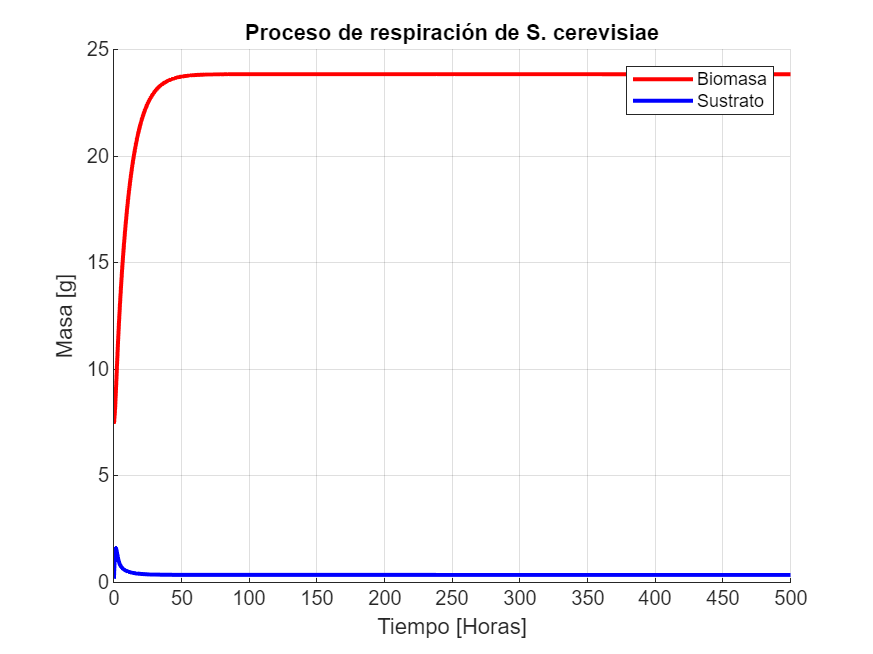

params={1};
for i=1:length(params)

    sim_out = sim('TP4', simConfig);
    
    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time));
    mu = sim_out.mu_s.Data;
    
end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Proceso de respiración de S. cerevisiae');
xlabel('Tiempo [Horas]');
ylabel('Masa [g]');
plot(time, biomass, 'r', 'LineWidth', 2);
plot(time, sustrate, 'b', 'LineWidth', 2);
legend('Biomasa', 'Sustrato');

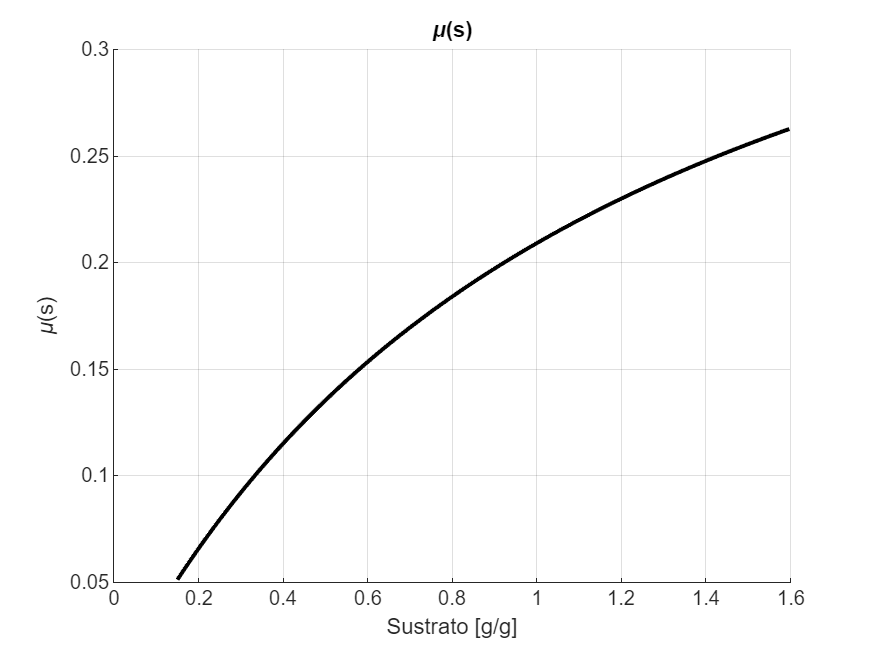


fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s)');
xlabel('Sustrato [g/g]');
ylabel('\mu(s)');
plot(sustrate, mu, 'k', 'LineWidth', 2);

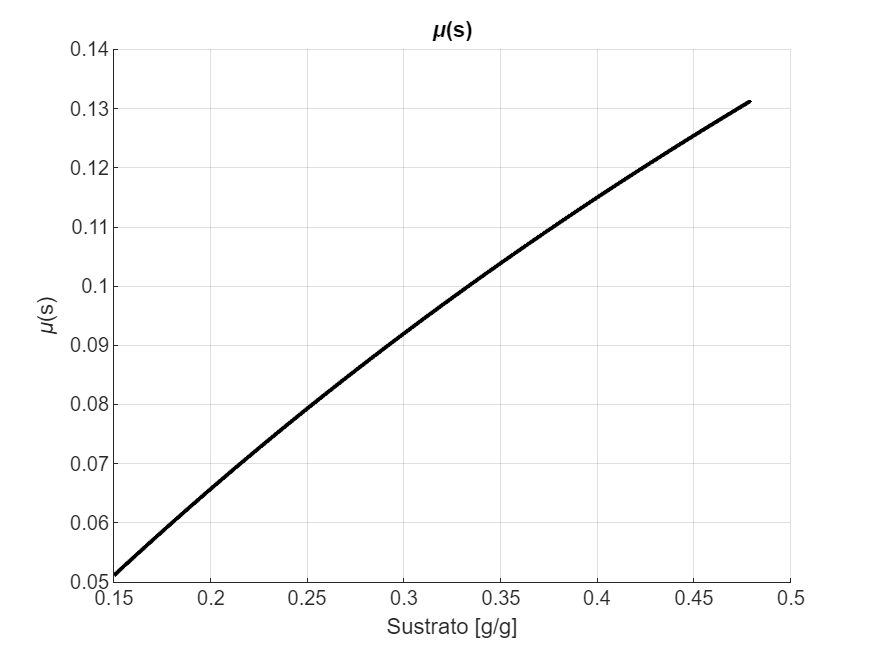

mu_r=0.23; % mu de referencia a operar

modelParameters.mu_r=mu_r;

params={1};
estimated_sustrate=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)

    sim_out = sim('TP4_control', simConfig);
    
    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time));
    mu = sim_out.mu_s.Data;
    
    % estimated_states = sim_out.estimated_states.Data;
    % estimated_sustrate{i} = reshape(estimated_states(:,1), size(time));
    % error{i}=(estimated_sustrate{i}-sustrate);
    % MSE{i} = immse(estimated_sustrate{i}, sustrate);

end

% fig = figure();
% set(fig,'Position',[0 0 800 600]);
% hold on; grid on;
% title('Proceso de respiración de S. cerevisiae');
% xlabel('Tiempo [Horas]');
% ylabel('Masa [g]');
% plot(time, biomass, 'r', 'LineWidth', 2);
% plot(time, sustrate, 'b', 'LineWidth', 2);
% legend('Biomasa', 'Sustrato');

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s)');
xlabel('Sustrato [g/g]');
ylabel('\mu(s)');
plot(sustrate, mu, 'b', 'LineWidth', 2);

plot(sustrate, mu_r, 'k--', 'LineWidth', 2);

% fig = figure();
% set(fig,'Position',[0 0 800 600]);
% hold on; grid on;
% title('Error absoluto de la estimación (concentración) (Kalman)');
% xlabel('Tiempo [Horas]');
% ylabel('Error Absoluto [g/g]');
% plot(time, abs(error{1}), 'LineWidth', 3);
% 
% legend(sprintf('(MSE=%.3f)', MSE{1}));